clc
clear all
%Simulation step
Tsim = 1e-6;
Tob  = 1/(20e3);
%Rated Machine Parameters in small signal model
Rs = 30e-3;
Ldd_inc= 80e-6;
Ldq_inc= -20e-6;
Lqq_inc= 200e-6;
L_inc = [Ldd_inc,Ldq_inc;Ldq_inc,Lqq_inc];
L_inc_inv = L_inc^-1;
J = [0,-1;1,0];
%Rated Machine Parameters in fundamental average model
Ld_ap = 90e-6;
Lq_ap = 300e-6;
Psi_dm = 0.054;
L_ap = [Ld_ap 0;0 Lq_ap];
%Mechanical Parameters
inertia = 4.7e-3;
damping = 2e-1; 
%To shorting the simulation time and show the effectiveness of the
%observer, a little inertia is choosen for this simulation.

%Operation Fundamental Frequency Current & Voltage
Id0 = -50;
Iq0 = 150;
we0 = 3000*4/60*2*pi;
Ud0 = Rs * Id0 - we0 * Lq_ap * Iq0;
Uq0 = Rs * Iq0 + we0 *(Ld_ap * Id0 + Psi_dm);


%Extra signal injection
Umd = 2;
Umq = 2;
weh = 40*2*pi;


%Init parameters in electrical parameters observer
Tdd = L_inc_inv(1,1); Tdq = L_inc_inv(1,2); Tqq = L_inc_inv(2,2);
R = 1 * diag([1 1]);
Q = 0.01 * diag([0.01 0.01 Rs Tdd Tdq Tqq]);
Qx = Q(1:2,1:2);
Qp = Q(3:6,3:6);
%Init parameters in mechanical parameters observer
K_inertia = 1e-5;
K_damping = 1e1;

%percentage of the initial value of the observed parameters
initial_percentage_matrix = [0.2,0.4,0.8,1.2,1.4,1.6,1.8];
% sim_data = zeros(1,7);
for i = 1:length(initial_percentage_matrix)
    initial_percentage = initial_percentage_matrix(i);
    sim_data(i) = sim("Sim.slx");
end
% sim_data
% sim_data.Damping_Est{1}.Values

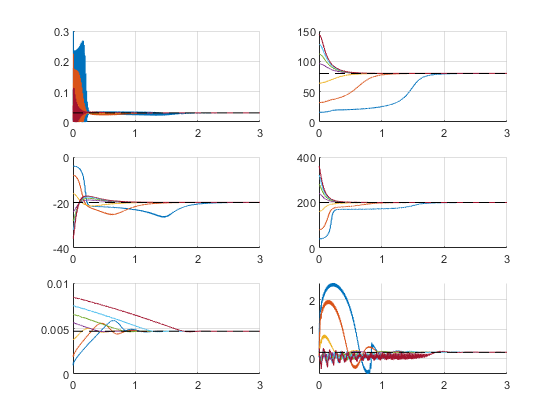

figure()
subplot(3,2,1)
for i = 1:length(initial_percentage_matrix)
    hold on
    plot(sim_data(i).Rs_Est{1}.Values.Time,sim_data(i).Rs_Est{1}.Values.Data)    
end
plot([0,3],[Rs,Rs],'--','Color',[0,0,0])
hold off
xlim([0 3])
ylim([0 0.3])
grid on

subplot(3,2,2)
for i = 1:length(initial_percentage_matrix)
    hold on
    plot(sim_data(i).Ldd_Est{1}.Values.Time,sim_data(i).Ldd_Est{1}.Values.Data.*1e6)    
end
plot([0,3],[Ldd_inc*1e6,Ldd_inc*1e6],'--','Color',[0,0,0])
hold off
xlim([0 3])
grid on

subplot(3,2,3)
for i = 1:length(initial_percentage_matrix)
    hold on
    plot(sim_data(i).Ldq_Est{1}.Values.Time,sim_data(i).Ldq_Est{1}.Values.Data.*1e6)    
end
plot([0,3],[Ldq_inc*1e6,Ldq_inc*1e6],'--','Color',[0,0,0])
hold off
xlim([0 3])
grid on

subplot(3,2,4)
for i = 1:length(initial_percentage_matrix)
    hold on
    plot(sim_data(i).Lqq_Est{1}.Values.Time,sim_data(i).Lqq_Est{1}.Values.Data.*1e6)    
end
plot([0,3],[Lqq_inc*1e6,Lqq_inc*1e6],'--','Color',[0,0,0])
hold off
xlim([0 3])
grid on

subplot(3,2,5)
for i = 1:length(initial_percentage_matrix)
    hold on
    plot(sim_data(i).Inertia_Est{1}.Values.Time,sim_data(i).Inertia_Est{1}.Values.Data)    
end
plot([0,3],[inertia,inertia],'--','Color',[0,0,0])
hold off
xlim([0 3])
grid on

subplot(3,2,6)
for i = 1:length(initial_percentage_matrix)
    hold on
    plot(sim_data(i).Damping_Est{1}.Values.Time,sim_data(i).Damping_Est{1}.Values.Data)    
end
plot([0,3],[damping,damping],'--','Color',[0,0,0])
hold off
xlim([0 3])
grid on